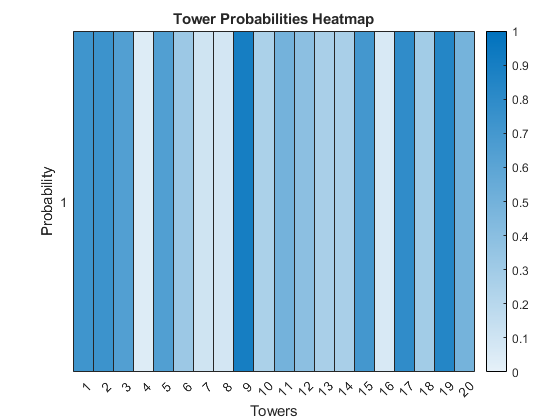

% Define the parameters
clc; clear;
numAnts = 4;
numIterations = 5;
alpha = 1.0;   % Pheromone importance
beta = 2.0;    % Distance importance
evaporationRate = 0.1;

% Generate random tower positions and probabilities
numTowers = 20;
towerProbabilities = rand(numTowers, 1);

% Reshape the array for heatmap
heatmapData = reshape(towerProbabilities, 1, []);

% Plot the heatmap
figure;
heatmap(heatmapData, 'ColorLimits', [0, 1], ...
    'XLabel', 'Towers', 'YLabel', 'Probability', 'Title', 'Tower Probabilities Heatmap');

antSolutions = 4×1 cell array
    {9×1 double}
    {9×1 double}
    {9×1 double}
    {9×1 double}


ans =      4     5     6    11    12    13    15    16    17


Iteration 1: Min Average Probability = 0.4097


antSolutions = 4×1 cell array
    {9×1 double}
    {9×1 double}
    {9×1 double}
    {9×1 double}


ans =      4     5     6    11    12    13    15    16    17


Iteration 2: Min Average Probability = 0.4097


antSolutions = 4×1 cell array
    {9×1 double}
    {9×1 double}
    {9×1 double}
    {9×1 double}


ans =      3     4     5     9    10    11    14    15    16


Iteration 3: Min Average Probability = 0.4097


antSolutions = 4×1 cell array
    {9×1 double}
    {9×1 double}
    {9×1 double}
    {9×1 double}


ans =      1     2     3     8     9    10    12    13    14


Iteration 4: Min Average Probability = 0.4097


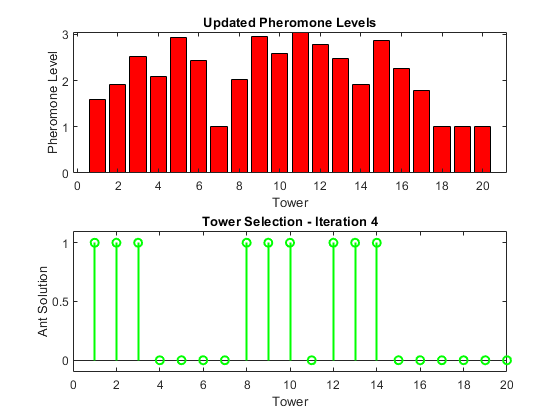

Index exceeds the number of array elements (20).



% Define problem-specific parameters
k = 9;    % Number of TLAs to install
minConsecutiveTLAs = 3;

% Initialize pheromone levels
pheromoneLevels = ones(numTowers, 1);

% Initialize the best solution and its probability
bestSolution = [];
minAvgProbability = 1;

for iteration = 1:numIterations
    antSolutions = cell(numAnts, 1); % Empty array
    antProbabilities = zeros(numAnts, 1);
    
    for ant = 1:numAnts
        visited = false(numTowers, 1); % Logical zeros
        antSolution = zeros(k, 1); % TLAs install index, black = 1, white = 0
        
        % Construct the solution
        for tower = 1:numTowers
            
            if tower == 1
                visited(1) = true;
                toss = randi([0,1]); % fair random for the first tower (fix this to pheromone later)
                if toss == 0
                    continue
                else
                    antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs);
                end
            end
            
            if tower == 2
                visited(2) = true; 
                if ismember(tower-1, antSolution) % i-1 black
                    continue
                else % i-1 white
                    toss = randi([0,1]);
                    if toss == 0
                        continue
                    else
                        antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs);
                    end
                end
            end
            
            if tower >= 3 % problem is here
                visited(tower) = true;
                if ismember(tower - 2,antSolution) % i-2 black
                    if ismember(tower - 1,antSolution) % i-1 black
                        if ismember(tower, antSolution) % i black
                            continue
                        else % i white
                            toss = randi([0,1]);
                            if toss == 0
                                continue
                            else
                                antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs);
                            end
                        end
                    else % i-1 white
                        % should random with pheromone
                        toss = randi([0,1]);
                        if toss == 0
                            continue
                        else
                            antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs);
                        end
                    end
                else % i-2 white
                    if ismember(tower - 1,antSolution) % i-1 black
                        if ismember(tower, antSolution) % i black
                            continue
                        else % i white
                            not_installed = find(~antSolution);
                            antSolution(not_installed) = tower;
                        end
                    else % i-1 white
                        % should random with pheromone
                        toss = randi([0,1]);
                        if toss == 0
                            continue
                        else
                            antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs);
                        end
                    end
                end
                
            end % end of tower construction loop

            % Calculate probabilities for unvisited towers
            unvisitedIndices = find(~visited); % find the index of zero element
            probabilities = (pheromoneLevels(unvisitedIndices) .^ alpha) .* (towerProbabilities(unvisitedIndices) .^ beta);
            probabilities = probabilities / sum(probabilities);
            
        end

        antSolutions{ant} = antSolution;
        antProbabilities(ant) = mean(towerProbabilities(antSolution));
        
    end
    antSolutions
    % Update pheromone levels based on the best ant solution
    [~, bestAnt] = min(antProbabilities);
    bestAntSolution = antSolutions{bestAnt};
    bestAntSolution'
    
    for i = 1:k - minConsecutiveTLAs + 1
        subSolution = bestAntSolution(i:i + minConsecutiveTLAs - 1);
        avgProbability = mean(towerProbabilities(subSolution));
        pheromoneLevels(subSolution) = (1 - evaporationRate) * pheromoneLevels(subSolution) + avgProbability;
    end
    
    % Update the best solution if a better one is found
    if antProbabilities(bestAnt) < minAvgProbability
        bestSolution = bestAntSolution;
        minAvgProbability = antProbabilities(bestAnt);
    end
    
    % Display the best solution in this iteration
    fprintf('Iteration %d: Min Average Probability = %.4f\n', iteration, minAvgProbability);
    
    % Plot the tower selection for the best ant
    subplot(2, 1, 2);
    plotAntSolution(bestAntSolution, numTowers);
    title(['Tower Selection - Iteration ' num2str(iteration)]);
    xlabel('Tower');
    ylabel('Ant Solution');

    % Pause for visualization (adjust as needed)
    pause(1);

    % Plot the updated pheromone levels
    subplot(2, 1, 1);
    bar(1:numTowers, pheromoneLevels, 'r');
    title('Updated Pheromone Levels');
    xlabel('Tower');
    ylabel('Pheromone Level');

    % Pause for visualization (adjust as needed)
    pause(1);
end

% Display the final best solution and its average probability
fprintf('Final Best Solution:\n');
fprintf('Average Probability = %.4f\n', minAvgProbability);
fprintf('TLA Positions = %s\n', mat2str(bestSolution));


function antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs)
    not_installed = find(~antSolution);
    sumNonZero = sum(antSolution ~= 0);
    k_remain = k - sumNonZero;

    if k_remain >= 2*minConsecutiveTLAs % install 3 TLAs
        for i = not_installed:minConsecutiveTLAs + not_installed - 1
            antSolution(i) = tower + i - 1;
        end
    else % install all TLAs left
        for i = not_installed:k_remain + not_installed - 1
            antSolution(i) = tower + i - 1;
        end    
    end 
end
function choice = chooseWithProbability(probabilities)
    cumulativeProbabilities = cumsum(probabilities);
    if ~isempty(cumulativeProbabilities)
        randValue = rand() * cumulativeProbabilities(end);
        choice = find(randValue <= cumulativeProbabilities, 1, 'first');
    else
        % Handle the case when cumulativeProbabilities is empty
        choice = [];
    end
end
% Function to plot the tower selection for an ant solution
function plotAntSolution(antSolution, numTowers)
    antPlot = zeros(1, numTowers);
    antPlot(antSolution(antSolution ~= 0)) = 1;
    stem(1:numTowers, antPlot, 'g', 'LineWidth', 1.5);
    ylim([-0.1, 1.1]);
end